% VARS 4 FIGS - need indicies for trials that meet criteria
% CONTRAST calc's
% this part needed for any loops involving looping over CONTRAST:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1x96 struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, etc
    con(i) = stimDetails(i).targContrast; % making vector with list of targ contrast for each condition - some of these will be repeating, since there are only 3 contrasts but 96 stimulus conditions (phase, etc)
end

conOrderedByTrial = con(trialCond); % trial cond is all conditions ordered by trial..its indicies for rows in stimDetail
conOrderedByTrialMeetCriteria = conOrderedByTrial(:,idxOnsetsMeetsCriteria);
uniqueContrasts = unique(con); % for looping over contrast values later


%%  DURATION Calc's
% this part needed for any loops involving looping over DURATION:

% extract contrast field from stimDetails
for i=1:length(stimDetails); % 1 by # stim conditions struct, each row is a stim condition , w/colums fields like sf, correctResp, contrasts, duration, etc
    dur(i) = stimDetails(i).duration; % making vector with list of stim duration for each condition - some of these will be repeating, since there are only 5? durations but many stimulus conditions (phase, etc)
end

durOrderedByTrial = dur(trialCond); 
durOrderedByTrialMeetCriteria = durOrderedByTrial(:,idxOnsetsMeetsCriteria);
uniqueDurations = unique(dur);

%% CON & DUR TOGETHER

% putting together dur & con so that I can index into the trials in order w/trialCond
conAndDur = [con; dur];
% put it in order of trial presentation:
conAndDurOrderedByTrial = conAndDur(:,trialCond); % gives 2 x #trials
conAndDurOrderedByTrialMeetCriteria = conAndDurOrderedByTrial(:,idxOnsetsMeetsCriteria); 


% legend info

reigons = {'V1','LM','AL','AM','control'};

cons4Legend = arrayfun(@num2str, uniqueContrasts, 'UniformOutput', 0) % max contrast is '1'

cons4Legend =     '0'    '0.03'    '0.0625'    '0.125'    '0.25'    '0.5'    '1'


cons4Axes = arrayfun(@num2str, uniqueContrasts*100, 'UniformOutput', 0) % max contrast is 100% 

cons4Axes =     '0'    '3'    '6.25'    '12.5'    '25'    '50'    '100'



%dursFrame2ms = (uniqueDurations/60)*1000;
durs4Legend = arrayfun(@num2str, uniqueDurations, 'UniformOutput', 0)

durs4Legend =     '6'


durs4Axes = durs4Legend;


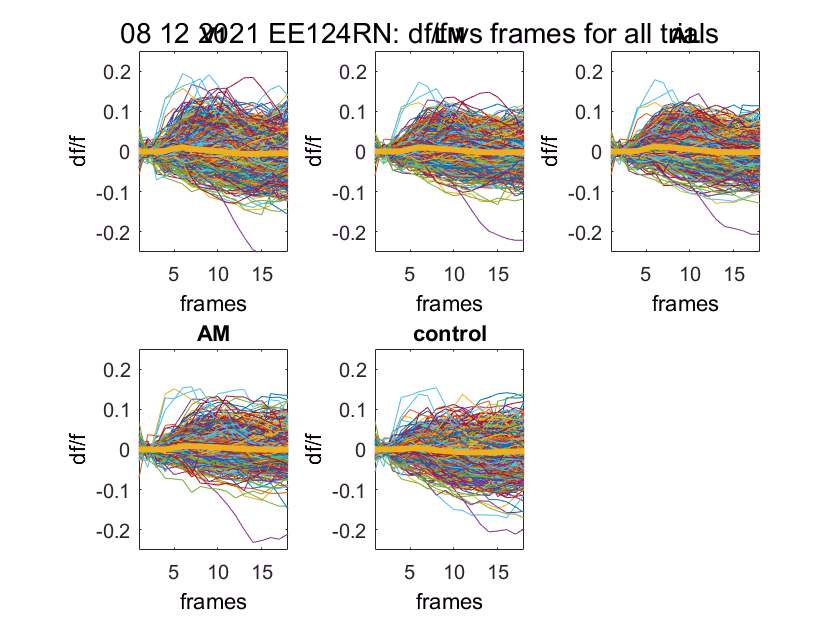

% ALL TRIALS - ONE FIG, SUBPLOTS = POINTS, ALL TRACES/trials, df/f vs frames
% all VIS AREAS
% all STIM CONDs

figure % make one figure for all subplots
clear titleText
titleText = ': df/f vs frames for all trials'; % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear recomboOnePtAllFramesAllTrialMinusMeanBase
    clear meanRecomboOnePtAllFramesAllTrialMinusMeanBase
    
    % collect all trials over all frames for the ith point
    clear onePtAllFramesAndTrials % new var each point
    onePtAllFramesAndTrials = squeeze(PTSdfof(i,:,:)); 
    onePtAllFramesAndTrials = onePtAllFramesAndTrials';
            
    % for every trace, subtract the baseline value at that point from each frame value
    clear tr % for each trial in onePtAllFramesAndTrial
    for tr = 1:size(onePtAllFramesAndTrials,1) % 1st dim is trials, 2nd is frames
        
        % getting TRIAL VECTOR
        clear onePtAllFramesOneTrial % make new var for each trial
        % index into each trace/vector & save as variable
        onePtAllFramesOneTrial = onePtAllFramesAndTrials(tr,:);
            
        % getting MEAN BASEline VALUE for each TRIAL
        clear allBaseFramesOnePtOneTrial % new baseline frames for each trial
        % collect 4 baseline frames for tr-th ith trial
        allBaseFramesOnePtOneTrial = onePtAllFramesOneTrial(1,baselineIdx);
        
        clear mean4baseFramesOnePtOneTrial
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneTrial = mean(allBaseFramesOnePtOneTrial,2);
        mean4baseFramesOnePtOneTrial = squeeze(mean4baseFramesOnePtOneTrial);
            
        % BASEline CORRECTion of TRIAL VECTOR
        % new baseline-corrected trace for each trial
        onePtAllFramesOneTrialMinusMeanBase = onePtAllFramesOneTrial-mean4baseFramesOnePtOneTrial;
        
        % collect CORRECTed TRIAL VECTORS in matrix
        % (only clear this outside the loop for each point)
        recomboOnePtAllFramesAllTrialMinusMeanBase(tr,:) = onePtAllFramesOneTrialMinusMeanBase;
            
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtAllFramesOneTrialMinusMeanBase); % length of frames
        % plot one baseline corrected trace at a time
        subplot(2,3,i) % make a subplot
        plot(x_axis,onePtAllFramesOneTrialMinusMeanBase)
                
        hold on % hold for next trial
                
    end % end tr loop
      
    hold on % hold for plotting mean over subplot
        
    % get mean baselined trace across all trials
    meanRecomboOnePtAllFramesAllTrialMinusMeanBase = mean(recomboOnePtAllFramesAllTrialMinusMeanBase,1); % mean across trials
   
    plot(x_axis,meanRecomboOnePtAllFramesAllTrialMinusMeanBase,'linewidth',3)
    title(reigons{i})
        
    ylim([-0.25 0.25]) 
    xlim([1 length(x_axis)])
    ylabel('df/f')
    xlabel('frames')

    ax = gca;
    x.XTick = [1:1:length(x_axis)];
       
end % end i loop

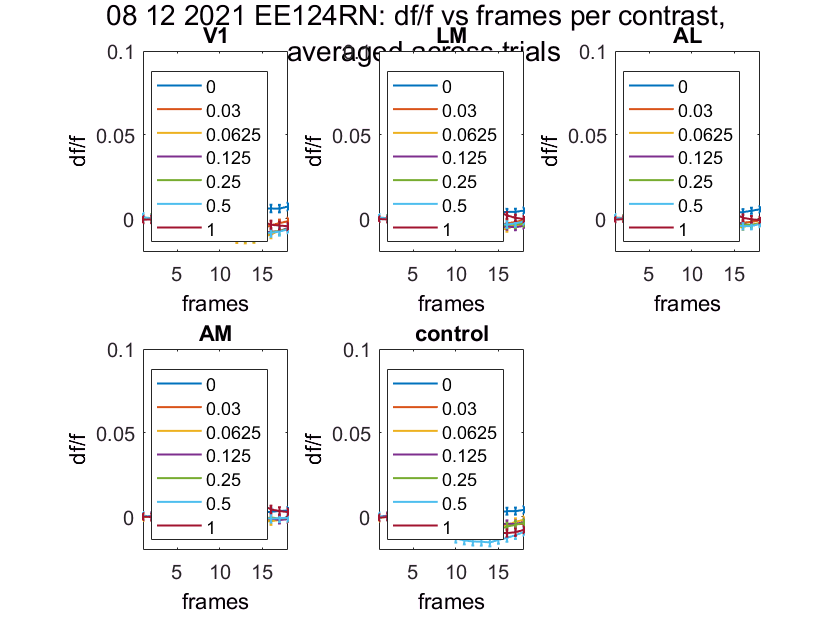

% MEAN across TRIALS 
% all VIS AREAS
% CONTRAST

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per contrast, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) % for each contrast
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneCon
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneCon = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneConMinusMeanBase
        onePtOneConMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneCon;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneConMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,c) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneConMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneConMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end c loop
            
hold on
legend(cons4Legend)
                
end % end i loop

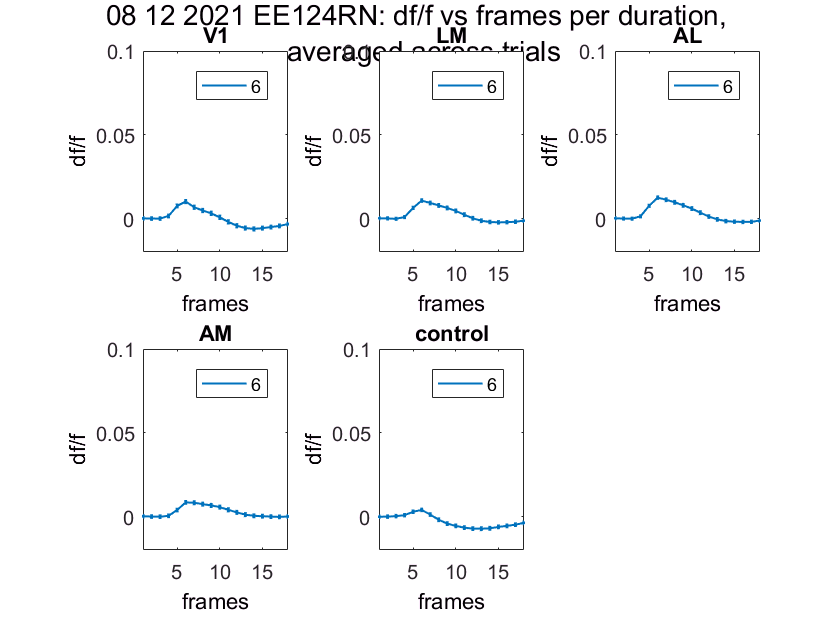

% MEAN across TRIALS 
% all VIS AREAS
% DURATION

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': df/f vs frames per duration, \n averaged across trials'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));
    
clear recomboOnePtAllFramesAllTrialMinusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear d
    for d = 1:length(uniqueDurations) % for each contrast
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % MEAN over trials
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % creating a 
        % 1x # trials variable that has dfof of one point averaged across trials
        % at the c-th contrast, for all frame
                
        % mean BASEline - now is a good time to calculate baseline, because we already selelcted the cth
        % trials and we already took the mean across trials
        clear allBaseFramesMeanOverTrialsPTSdfof % new baseline frames for each trace
        % collect 4 baseline frames 
        allBaseFramesMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof(1,baselineIdx); % take the baseline frame
        clear mean4baseFramesOnePtOneDur
        % get mean value of baseline values for ith point
        mean4baseFramesOnePtOneDur = mean(allBaseFramesMeanOverTrialsPTSdfof,2); % mean baseline value
                
        % BASEline CORRECTION
        % new baseline-corrected trace for each mean trace
        clear onePtOneDurMinusMeanBase
        onePtOneDurMinusMeanBase = meanOverTrialsPTSdfof-mean4baseFramesOnePtOneDur;
        
        % COLLECT corrected traces in matrix
        % (only clear this each tine go thru i loop (new one each subplot)
        recomboOnePtAllFramesAllTrialMinusMeanBase(c,:) = onePtOneDurMinusMeanBase;
            
        % STDEV of deviation from the mean oover trials
         clear err
        % our mean trace is averaged over trials. We want to know how much the trials 
        % values varied, not how much the mean trial values vary over time...
        err = std(PTSdfof(i,:,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
                
        % for later group analysis - for each contrast, a trace for the i-th point
        % forGroupMeanOverTrialsPTSdfof(:,:,d) = meanOverTrialsPTSdfof; % all rows (points, ann columns(frames) for this contrast (c)
                
        % PLOT
        clear x_axis
        x_axis = 1:length(onePtOneDurMinusMeanBase);
        subplot(2,3,i)
        errorbar(x_axis,onePtOneDurMinusMeanBase,err,'linewidth',1)
        ylim([-0.02 0.1])  
        xlim([1 length(x_axis)])
        title(reigons{i})
        ylabel('df/f')
        xlabel ('frames')
        
        hold on % all contrast traces on one fig
                
    end % end d loop
            
hold on
legend(durs4Legend)
                
end % end i loop

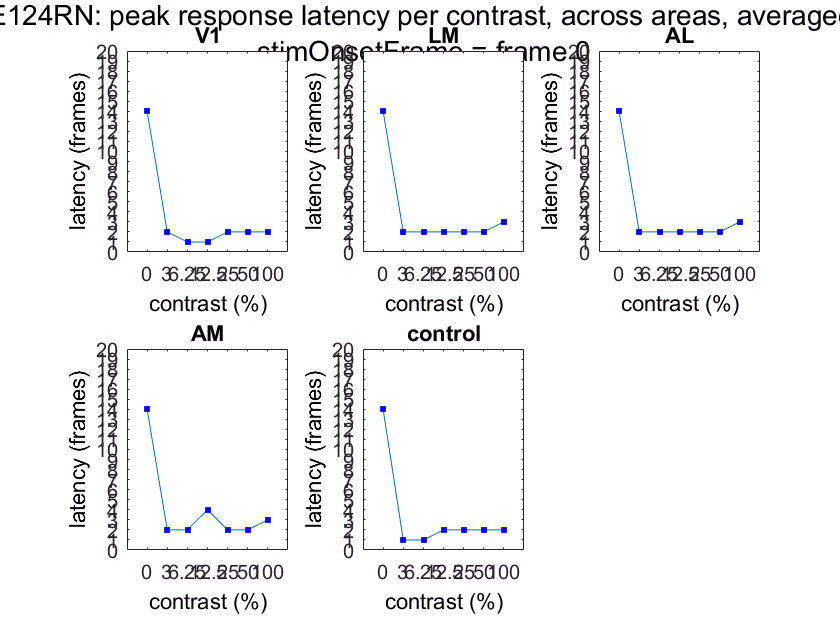

% CON LATENCY 
% find the max, and then the frame the max is at

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': peak response latency per contrast, across areas, averaged across trials \n stimOnsetFrame = frame 0'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts)
    
    clear allConLatencyInFrames % clear latency curves between points
    clear stdErr % clear stdErr of latency curves
    
    clear c
    for c = 1:length(uniqueContrasts)
        
        % MEAN over TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,cthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        
        % BASEline CORRECTions
        clear baselineFramesOverTrialsPTSdfof
        baselineFramesOverTrialsPTSdfof = meanOverTrialsPTSdfof(:,baselineIdx);
        clear meanBaselineFramesOverTrialsPTSdfof
        meanBaselineFramesOverTrialsPTSdfof = mean(baselineFramesOverTrialsPTSdfof);
        clear baselinedMeanOverTrialsPTSdfof
        baselinedMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof-meanBaselineFramesOverTrialsPTSdfof;
        
        % FIND MAX
        clear maxBaselinedMeanOverTrialsPTSdfof 
        maxBaselinedMeanOverTrialsPTSdfof = max(baselinedMeanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        clear latencyInFrames
        latencyInFrames = find(baselinedMeanOverTrialsPTSdfof == maxBaselinedMeanOverTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        clear latencyRel2StimOnsetFrame
        latencyRel2StimOnsetFrame = latencyInFrames-stimOnsetFrame;
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        conLatencyInFrames(1,c) = latencyRel2StimOnsetFrame; % one row, each 7 columnns    
        
        % STDEV
        % we want to know the variation in latency over trials at each contrast,
        % only for the peak activity frames (based off calculation, not pix wise image)
        stdErr(1,c) = std(PTSdfof(i,latencyInFrames,cthTrials),[],3)/sqrt(sum(cthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    %convertFrames2Sec = 0.1*conLatencyInFrames;
    
    % still w/in the points loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     x_axis = 1:length(conLatencyInFrames);
     errorbar(x_axis,conLatencyInFrames,stdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     title(reigons{i})
     
     ylim([0 20]) 
     xlim([0 8])
     
     set(gca,'xtick',1:length(uniqueContrasts)); 
     set(gca,'xticklabel',cons4Axes);
     
     set(gca,'ytick',[0:20]);
     
     xlabel('contrast (%)')
     ylabel('latency (frames)')
     
end

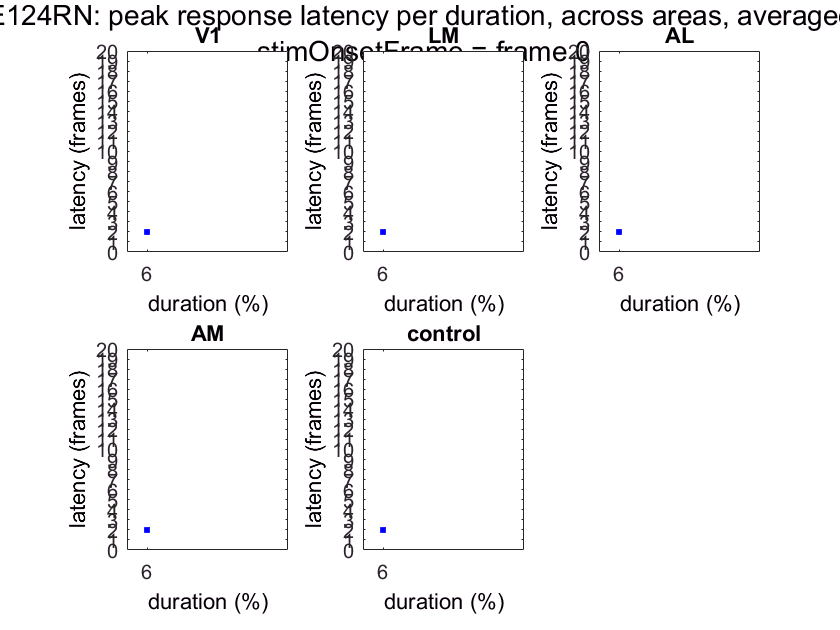

% CON LATENCY 
% find the max, and then the frame the max is at

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': peak response latency per duration, across areas, averaged across trials \n stimOnsetFrame = frame 0'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts)
    
    clear allDurLatencyInFrames % clear latency curves between points
    clear stdErr % clear stdErr of latency curves
    
    clear c
    for d = 1:length(uniqueDurations)
        
        % MEAN over TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        clear meanOverTrialsPTSdfof
        meanOverTrialsPTSdfof = mean(PTSdfof(i,:,dthTrials),3); % take the mean trace across trials, leaving dfof vs frames
        
        % BASEline CORRECTions
        clear baselineFramesOverTrialsPTSdfof
        baselineFramesOverTrialsPTSdfof = meanOverTrialsPTSdfof(:,baselineIdx);
        clear meanBaselineFramesOverTrialsPTSdfof
        meanBaselineFramesOverTrialsPTSdfof = mean(baselineFramesOverTrialsPTSdfof);
        clear baselinedMeanOverTrialsPTSdfof
        baselinedMeanOverTrialsPTSdfof = meanOverTrialsPTSdfof-meanBaselineFramesOverTrialsPTSdfof;
        
        % FIND MAX
        clear maxBaselinedMeanOverTrialsPTSdfof 
        maxBaselinedMeanOverTrialsPTSdfof = max(baselinedMeanOverTrialsPTSdfof); % take the max value
        % once you have the max value at that contrast, find the frame (column index) it corresponds to
        clear latencyInFrames
        latencyInFrames = find(baselinedMeanOverTrialsPTSdfof == maxBaselinedMeanOverTrialsPTSdfof); % LATENCY in imaging frames, assign it to variable
        clear latencyRel2StimOnsetFrame
        latencyRel2StimOnsetFrame = latencyInFrames-stimOnsetFrame;
        % One 10 Hz imaging frame = 0.1 second per frame
        % Collect cth latency values into a vector that should be the same length as maxContRespOverFramesTrialsPTSdfof 
        durLatencyInFrames(1,d) = latencyRel2StimOnsetFrame; % one row, each 7 columnns    
        
        % STDEV
        % we want to know the variation in latency over trials at each contrast,
        % only for the peak activity frames (based off calculation, not pix wise image)
        stdErr(1,d) = std(PTSdfof(i,latencyInFrames,dthTrials),[],3)/sqrt(sum(dthTrials)); % across all trials = 3rd dim
        
    end 
    
    % right now we're in frames, we need to be in seconds 
    clear convertFrames2Sec
    % once you have the vector for latencies for one point complete, convert it from frames to secondsfor one point
    format short g
    %convertFrames2Sec = 0.1*conLatencyInFrames;
    
    % still w/in the points loop, now that we've collected vector of
    % latencies for each contrast, plot on subplot for each point
     subplot(2,3,i)
     x_axis = 1:length(durLatencyInFrames);
     errorbar(x_axis,durLatencyInFrames,stdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue')
     title(reigons{i})
     
     ylim([0 20]) 
     xlim([0 8])
     
     set(gca,'xtick',1:length(uniqueDurations)); 
     set(gca,'xticklabel',durs4Axes);
     
     set(gca,'ytick',[0:20]);
     
     xlabel('duration (%)')
     ylabel('latency (frames)')
     
end

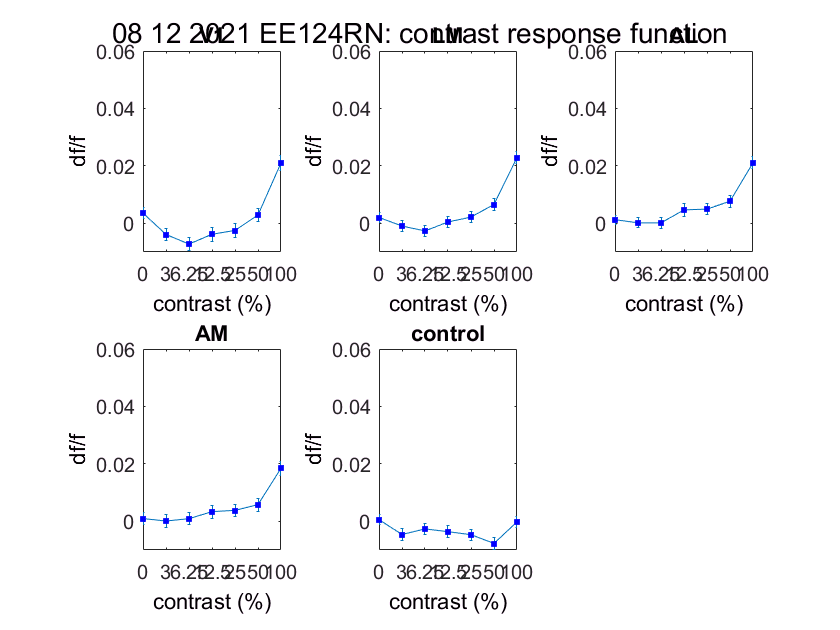

% CRF - LOG
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': contrast response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear contStdErr
clear crf
clear CRFminusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) 
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtCthTrials
        baselineFramesIthPtCthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtCthTrial
        meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    x_axis = 1:length(uniqueContrasts);
    %x_axis = uniqueContrasts;
    
%     errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
%     MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
%     title(reigons{i})
    
    errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    title(reigons{i})
    
    %ylim([-0.01 0.05]) 
    ylim([-0.01 0.06])
    %xlim([0, 1.03])
    xlim([min(x_axis), max(x_axis)])
    
    set(gca,'xtick',1:length(uniqueContrasts)); 
    set(gca,'xticklabel',cons4Axes);
    
%     clear xt
%     %xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%     % xt={'0'; '1' ; '2' ; '3';'4'} ; 
%     set(gca,'xtick',1:7); 
%     % set(gca,'xtick',1:5); 
%     set(gca,'xticklabel',cons4Axes);

    ylabel('df/f')
    xlabel('contrast (%)')
            
end % end i loop

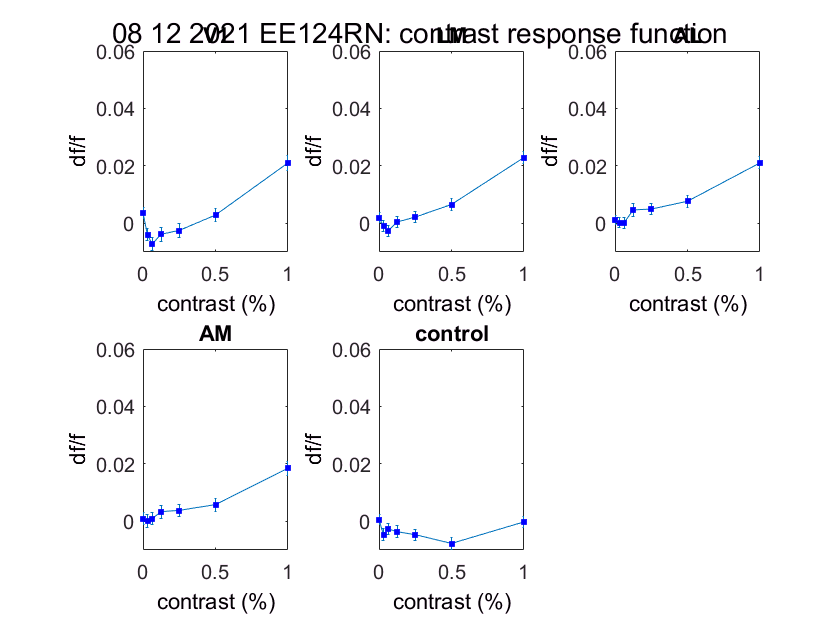

% CRF - NON log
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': contrast response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear contStdErr
clear crf
clear CRFminusMeanBase

clear i
for i = 1:length(xPickedPts) % for each point
        
    clear c
    for c = 1:length(uniqueContrasts) 
                
        % TRIALS
        clear cthTrials
        cthTrials = conOrderedByTrialMeetCriteria == uniqueContrasts(c); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        crf(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtCthTrials
        baselineFramesIthPtCthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtCthTrial
        meanBaselineFramesIthPtCthTrials = mean(baselineFramesIthPtCthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtCthTrials = mean(meanBaselineFramesIthPtCthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        CRFminusMeanBase(c) = crf(c)-meanBaselineFramesIthPtCthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthTrials)); % sum trials, not length
        contStdErr(1,c) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    %x_axis = 1:length(uniqueContrasts);
    x_axis = uniqueContrasts;
    
%     errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
%     MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
%     title(reigons{i})
    
    errorbar(x_axis,CRFminusMeanBase,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    title(reigons{i})
    
    ylim([-0.01 0.06]) 
    xlim([min(x_axis) max(x_axis)])
    
    %set(gca,'xtick',1:length(uniqueContrasts)); 
    %set(gca,'xticklabel',cons4Axes);

    ylabel('df/f')
    xlabel('contrast (%)')
            
end % end i loop

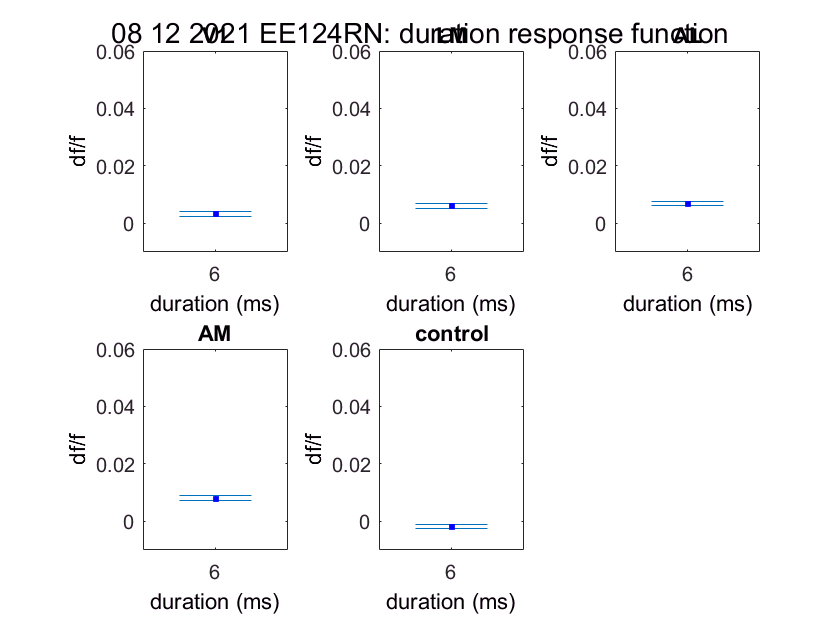

% DRF
% peak frames defined earlier

figure % make one figure for all subplots
clear titleText
titleText = sprintf(': duration response function'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
  
    clear durStdErr
    clear drf
    clear DRFminusMeanBase
    
    clear d
    for d = 1:length(uniqueDurations) 
                
        % TRIALS
        clear dthTrials
        dthTrials = durOrderedByTrialMeetCriteria == uniqueDurations(d); 
        
        % calculate CRF
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by # trials
        clear sq5FramesOverTrialsPTSdfof
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,dthTrials));
        % take the mean over frames, returns 1 x # trials
        clear meanOverFramesSq5FramesOverTrialsPTSdfof
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        % collect each c-th CRF value for this point
        drf(d) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % GET mean BASEline
        % the baseline for each CRF value is the mean of the baseline frames for
        % the ith point and cth contrast
        % get all frames & cth trials
        clear baselineFramesIthPtDthTrials
        baselineFramesIthPtDthTrials = squeeze((PTSdfof(i,baselineIdx,cthTrials)));
        % now have baseline frames x trials
        % take mean across trials 
        clear  meanBaselineFramesIthPtDthTrial
        meanBaselineFramesIthPtDthTrials = mean(baselineFramesIthPtDthTrials,2);
        % take mean across frames
        meanBaselineFramesIthPtDthTrials = mean(meanBaselineFramesIthPtDthTrials,1);
            
        % do BASEline CORRECTION
        % subtract the cth baseline from the flourescence at each c
        DRFminusMeanBase(d) = drf(d)-meanBaselineFramesIthPtDthTrials; % clear this var in between subplots

        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
        clear stdErr
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(dthTrials)); % sum trials, not length
        durStdErr(1,d) = stdErr; % clear outside i loop
        
    end % end contrast loop - have full baselined CRF for ith point
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,3,i)
    % 7 contrasts for x axis
    x_axis = 1:length(uniqueDurations);
    drfChart = errorbar(x_axis,DRFminusMeanBase,durStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue'); 
    
    title(reigons{i})
    ylim([-0.01 0.06]) 
    %xlim([min(x_axis), max(x_axis)])

    set(gca,'xtick',1:5); 
    set(gca,'xticklabel',durs4Axes);
    
    ylabel('df/f')
    xlabel('duration (ms)')
            
end % end i loop

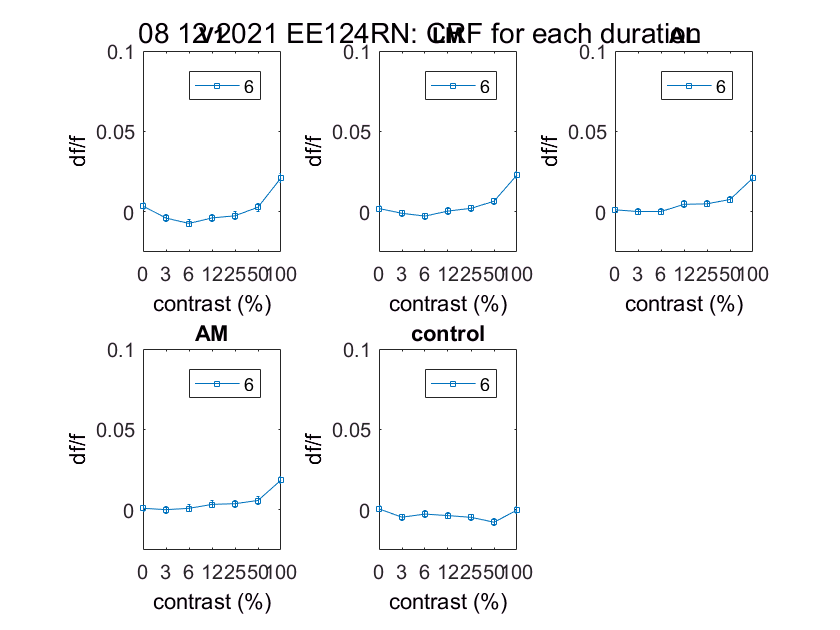

% CRF for each DURATION - LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': CRF for each duration'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [1:length(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

        clear xt
        xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        set(gca,'xtick',1:7); 
        set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Legend)
    
end % end i loop


% % now  I want the 6th subplot to be the
% % CRF for each duration across all points/visual areas
% 
% clear meanBaselineFramesIthPtCthDthTrials
% clear dthCRF
% clear stdErr
% clear contStdErr
% 
% for d = 1:length(uniqueDurations) % for each duration
%     
%     for c = 1:length(uniqueContrasts) % at each contrast
%  
%      clear cthDthTrials
%      cthDthTrials = conAndDurOrderedByTrialMeetCritera(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCritera(2,:) == uniqueDurations(d);
%      
%      % index cth dth trials
%      cthMeanOverPointsFramesTrials = mean(mean(squeeze(mean(PTSdfof(:,peakFrameIdx,cthDthTrials),1)),1)); % all pts, peak frames, only cth dth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,3)); % mean across trials for cthDth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,2)); % mean across frames for cthDth trials
%      meanDthCRFoverAllPts = squeeze(mean(cthMeanOverPointsFramesTrials,1)); % mean across points for cthDth trials
% 
%      % now I want to collect each c-th DRF value for this point
%      % creates 1 x # contrasts for the d-th duration
%      dthCRF(1,c) = meanDthCRFoverAllPts;
%      
%     % GET mean BASEline
%     clear baselineFramesIthPtCthDthTrials
%         baselineFramesIthPtCthDthTrials = (PTSdfof(:,baselineIdx,cthDthTrials));
%         % now have baseline frames x trials
%         % take mean across trials 
%         clear meanBaselineFramesIthPtCthDthTrials
%         meanBaselineFramesIthPtCthDthTrials = squeeze(mean(baselineFramesIthPtCthDthTrials,3));
%         % take mean across frames
%         meanBaselineFramesIthPtCthDthTrials = squeeze(mean(meanBaselineFramesIthPtCthDthTrials,2));
%         % take mean across visual areas
%         meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
%             
%         % do BASEline CORRECTION
%         % subtract the cth baseline from the flourescence at each c
%         dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots
% 
%         % STDERR
%         % now I want to calulate the StdErr for each CRF point calulated above
%         % (one err value for each contrast)
%         % that means I want the error over trials, not over frames
%         % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
%         clear stdErr
%         stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
%         contStdErr(1,c) = stdErr; % clear outside i loop
%         
%     end % end c loop
%              
%     % in d loop, for each duration plot CRF
%     
%         subplot(2,3,6) 
%         
%         % 7 contrasts for x axis
%         x_axis = [1:length(uniqueContrasts)];
%         errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
%         title('mean across visual areas')
%         
%         ylim([-0.025 0.1]) 
%         xlim([0, 8])
%         ylabel('df/f')
%         xlabel('contrast (%)')
% 
%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
%         set(gca,'xtick',1:7); 
%         set(gca,'xticklabel',xt);
%         
%         hold on 
%         
% end  % end d loop
% 
% hold on
% legend(durs4Legend)


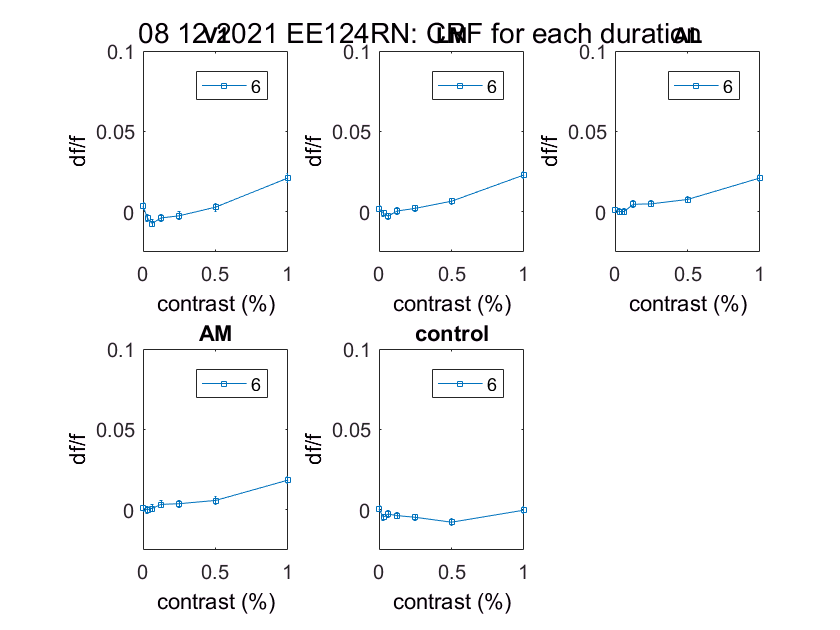

% CRF for each DURATION - not LOG
% all VIS AREAS

figure 
clear titleText
titleText = sprintf(': CRF for each duration'); % making char variables for sprintf/title later
suptitle(sprintf('%s', date, subjName, titleText));

clear i
for i = 1:length(xPickedPts) % for each point
    
    clear meanBaselineFramesIthPtCthDthTrials
    clear dthCRF
    clear stdErr
    clear contStdErr

    clear d
    for d = 1:length(uniqueDurations) % at each duration
    
        clear cthDthMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
        clear c
        for c = 1:length(uniqueContrasts) % for each duration at each contrast
            
             % for each POINT, for each DUR, get CRF at the dth dur

             clear cthDthTrials
             cthDthTrials = conAndDurOrderedByTrialMeetCriteria(1,:) == uniqueContrasts(c) & conAndDurOrderedByTrialMeetCriteria(2,:) == uniqueDurations(d);
             numTrials = sum(cthDthTrials);
             
             % this is the same as the CRF process from earlier code
             % getting AVG DF/F over 3 FRAMES & dthCthTRIALS for each CONTRAST at this DURATION
             % returns # frames by # trials
             clear sq5FramesOverTrialsPTSdfof
             sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,peakFrameIdx,cthDthTrials));
            
             % take the mean over frames
             % returns 1 x # trials
             clear meanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
         
             % now take the mean over trials
             clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof 
             meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof);
        
             % now I want to collect each c-th DRF value for this point
             % creates 1 x # contrasts for the d-th duration
             dthCRF(1,c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof; 
        
             % GET mean BASEline
             % the baseline for each CRF value is the mean of the baseline frames for
             % the ith point and cth contrast
             % get all frames & cth trials
             clear baselineFramesIthPtCthDthTrials
             baselineFramesIthPtCthDthTrials = squeeze((PTSdfof(i,baselineIdx,cthDthTrials)));
             % now have baseline frames x trials
             % take mean across trials 
             clear meanBaselineFramesIthPtCthDthTrials
             meanBaselineFramesIthPtCthDthTrials = mean(baselineFramesIthPtCthDthTrials,2);
             % take mean across frames
             meanBaselineFramesIthPtCthDthTrials = mean(meanBaselineFramesIthPtCthDthTrials,1);
            
             % do BASEline CORRECTION
             % subtract the cth baseline from the flourescence at each c
             dthCRF(c) = dthCRF(c)-meanBaselineFramesIthPtCthDthTrials; % clear this var in between subplots

            % STDERR
            % now I want to calulate the StdErr for each CRF point calulated above
            % (one err value for each contrast)
            % that means I want the error over trials, not over frames
            % that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x # trials)
            clear stdErr
            stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(cthDthTrials)); % sum trials, not length
            contStdErr(1,c) = stdErr; % clear outside j loop
             
        end % end c loop
     
        % once I've got that^ for the d-th duration, plot dth trace on ith subplot:
        subplot(2,3,i) 
        
        % 7 contrasts for x axis
        x_axis = [(uniqueContrasts)];
        errorbar(x_axis,dthCRF,contStdErr,'-s','MarkerSize',3) 
        title(reigons{i})
        
        ylim([-0.025 0.1]) 
        xlim([min(x_axis), max(x_axis)])
        ylabel('df/f')
        xlabel('contrast (%)')

%         clear xt
%         xt={'0'; '3' ; '6' ; '12' ; '25' ; '50'; '100'} ; 
        %set(gca,'xtick',1:7); 
        %set(gca,'xticklabel',xt);
        
        hold on 
        
    end % end d loop

hold on
legend(durs4Legend)
    
end % end i loop